## Week 3 Part 2 - Matlab Class

## Dave Hill

This will look at flow control and other programming goodies...

clear all
close all
home

## BLOCK 3.1

Let us start with for loops. A for loop allows a piece of code to repeatedly executed. A for loop is distinguished by a 'loop counter' variable. A for loop is typically used when the number of iterations is known PRIOR to going into the loop. The general structure is along these lines

% for [loop variable] = [range]
%    [stuff happens here]
% end

So, let's do a simple example...We are going to calculate the value of the sin function over a range of values. 

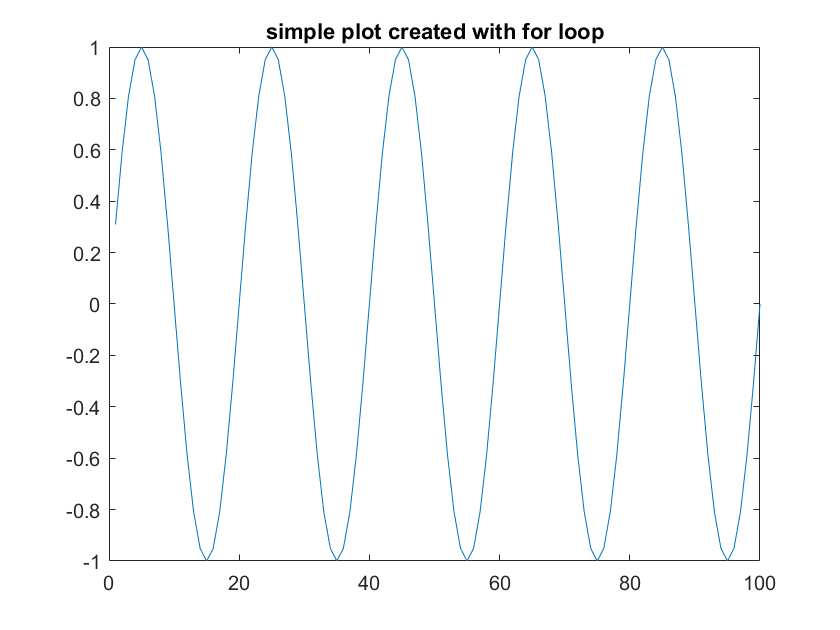

%an example
for n=1:100
    x(n)=sin(n*pi/10);
end
figure(1)
plot(x)
title('simple plot created with for loop')

Next, let us look at one of the most common errors made when people try to use loops:

for n=1:100
    x=sin(n*pi/10);
end
figure(2)
plot(x,'ro')     %what happened here?
title('Can you find the error?')

If you look carefully, you will see that we are NOT specifying the 'n-th' value of x each time in the loop. So, Matlab is NOT creating a vector, as we wish. Instead, every time through the loop, we just reassign a single value to the variable x. And, in the end we just have one value stored in x. From a 'debugging' point of view, remember that you have many ways of seeing the 'size' of variables and that can be really useful.

Well, what if our loop is empty?

for n=1:100
end

Ummm...this is ok in the sense that it will not throw an error, but nothing at all useful happened.

Next, note that we can easily 'nest' loops. Here, we have multiple counter variables. Think of a grid, or a checker-board, or a 2-d matrix. One counter variable goes along one side, and the other counter variable goes along the other side. And, you can easily extend this to 3, 4, or however many levels of nesting that you want. However, be aware that this can lead to a lot of calculations and can be slow.

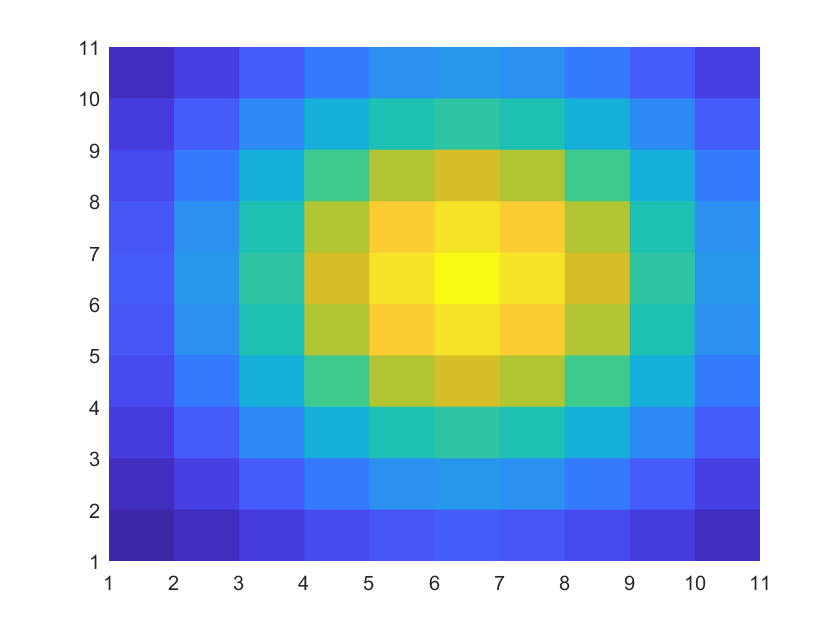

% As an example, let us compute a gaussian 'bump' and plot it. I will 'time' 
% the operation with the really cool tic-toc
tic
for x=1:11
    for y=1:11
        z(x,y)=exp(-((x-6)/4)^2-((y-6)/4)^2);
    end
end
figure(3)
pcolor(z);
shading flat

toc %So, the elapsed time between tic and toc will print to the screen

Elapsed time is 0.231723 seconds.


Ok that was pretty fast, but 'coarse'. Let's retry but with a MUCH larger 'grid'.

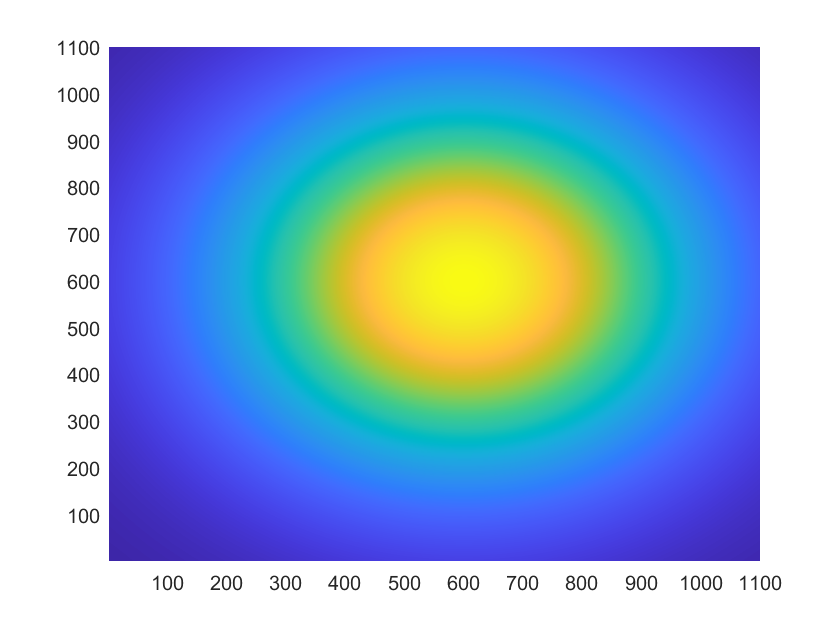

clear all
tic
for x=1:1100
    for y=1:1100
        z(x,y)=exp(-((x-600)/400)^2-((y-600)/400)^2);
    end
end
figure(4)
pcolor(z); shading flat

toc

Elapsed time is 0.703368 seconds.


So, this was a bit slower. So, nested for loops can become inefficient as they become large. And, using nested for loops for matrix-style computations is just not a good idea...it goes against the 'vectorized' nature of Matlab. As Matlab has improved over the years, it now does a lot of 'checks' of your code and will seek to correct / improve inefficienies where it can. The above is a good example. From the coarse to the fine case, we increased the number of operations by 10,000. The 'fine' case took longer to run, but it sure did not take 10,000 times longer.

Note that the 'loop variable' does not need to run from 1 to N in increments of 1. That IS the default, if write something like for n = 1:N. You can also have things count backwards:

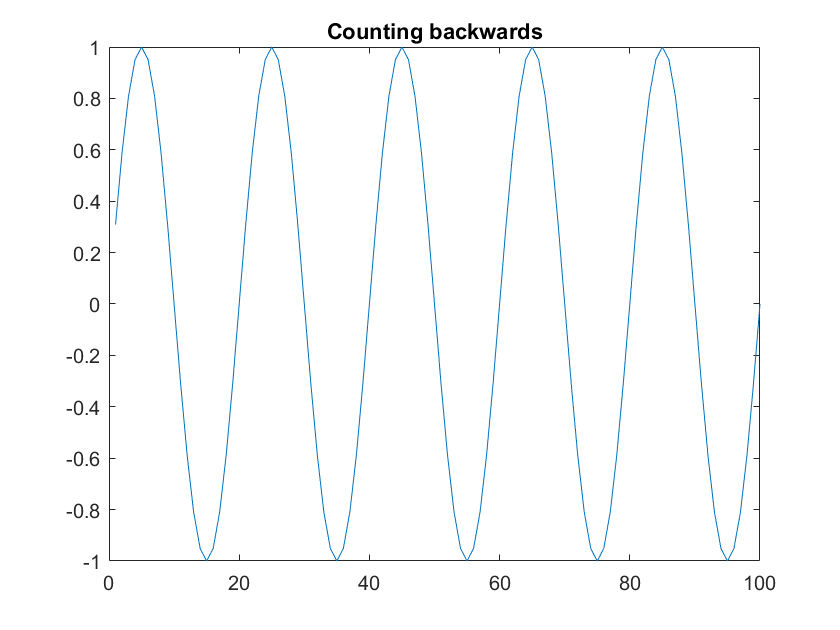

for n=100:-1:1
    x(n)=sin(n*pi/10);
end
figure(5)
plot(x)
title('Counting backwards')

Could you can also 'count' by fractions of an integer? For example

for n=1:.1:100
    x(n)=sin(n*pi/10);
end

Array indices must be positive integers or logical values.

Apparently not...This is because 'index' values for a variable must be, by definition, integers.

If, for some reason, you MUST count by some interval or over some range (negative integers) that will give you problems in terms of a subscript, you can bring in a placeholder counter variable.

counter=0; 
for n = 0: 0.1: 10 
	counter = counter + 1;
	x(counter) = sin(n*pi);
end
figure
plot(x)

## BLOCK 3.2

%Next, let us consider while loops. These are similar to for loops in that the general idea is to repeatedly execute some piece of code. However, the key difference is that, where a for loop uses a finite 'counter' to iterate through the code, a while loop uses some boolean (true or false) condition to determine whether or not to carry out another iteration. The general format is:

%while true
%   [do stuff]
%end

So, start with a simple example:

n=1;
while n<10
    disp(['n = ' num2str(n)])
    n=n+1;
end

n = 1
n = 2
n = 3
n = 4
n = 5
n = 6
n = 7
n = 8
n = 9


A potential problem with while loops is that you might get in a situation where the boolean argument is NEVER false and you are stuck in an infinite loop. For example, if you forget to 'increment' the counter. **DO NOT run this section...Instead, I would like you to cut and paste the text into the matlab command window. You will then have to hit ctrl-c to kill the operation.**

n=1;
while n<10
    disp(['n = ' num2str(n)])
end

The key point here is that there was nothing inside the while loop to change the value of n. So, n will NEVER reach 10 and the loop will never stop. Bad.

You can safeguard against this with a break command. Note that the example below uses an 'if' loop which we have not discussed yet, so sit tight on that until later. The main point here is that we have a safeguard that simply says, anthing beyond 25 operations and we stop.

n=1;
num_iterations=0;
while n<10
    disp(['n = ' num2str(num_iterations)])
    if num_iterations>25
        disp(['terminated at ' num2str(num_iterations) ' iterations'])
        break
    end
    num_iterations=num_iterations+1;
end

n = 0
n = 1
n = 2
n = 3
n = 4
n = 5
n = 6
n = 7
n = 8
n = 9
n = 10
n = 11
n = 12
n = 13
n = 14
n = 15
n = 16
n = 17
n = 18
n = 19
n = 20
n = 21
n = 22
n = 23
n = 24
n = 25
n = 26


terminated at 26 iterations


## BLOCK 3.3

Third, let us consider 'if' statments. These are not 'loops' in the sense that code does not get repeated. Rather, an if statement uses a boolean condition to decide whether or not to execute a certain piece of code. At its simplest, it looks like

%if true
%   [do stuff]
%end

So, let's do a simple example, checking to see if a given number is even or odd, using the mod function.

f=6

f = 6

%check if f is even
if mod(f,2)==0
    disp('f is even')
end

f is even


Since what followed the 'if' statement (on the same line) was 'true,' the code inside the if statement was executed.

The 'else' statement allows you to specify two possible things to do. If something is true, do A; if not, do B.

%if true
%   [do stuff]
%else
%   [do other stuff]
%end

Let's illustrate this with the same even / odd idea.

f=5

f = 5

%check if f is even
if mod(f,2)==0
    disp('f is even')
else
    disp('f is odd')
end

f is odd


Ok, nice. That worked...

There is a third variation on this, where we combine if, elseif, and else statments. The psuedo-code is:

%if true
%   [do stuff]
%elseif true
%   [do other stuff]
%else 
%   [do other other stuff]
%end

We can illustrate this simply with the example of checking to see if a number is positive or negative and, if it is neither, it must be zero.

f=12

f = 12

%check if f greater than zero, less than zero, or zero
if f>0
    disp('f is positive')
elseif f>10
    disp('f is negative')
else
    disp('looks like f is zero')
end

f is positive


## BLOCK 3.4

Finally, let us look at the 'switch' command. This is really just like a series of if / elseif commands. In many cases, using switch results in cleaner, more compact code. Here is an example

val=3;
switch val
    case 1
        disp('one')
    case 2
        disp('two')
    case 3
        disp('three')
    otherwise
        disp('something else')
end

three


There are endless variants on this:

val='hi'

val = 'hi'

switch val
    case 'goodbye'
        disp('no, I said hello, not goodbye')
    case 'hello'
        disp('hello back, have a good day')
end